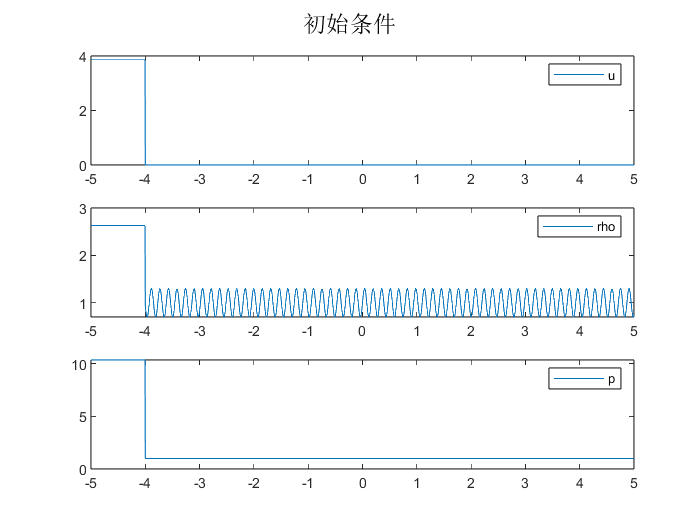

clear;clc;
dt = 0.001; % 时间推进的步长
dx_exact = 10/2000; % '精确解'的步长
dx_200 = 10/200; % 200个网格点的参考解

A = 0.3;
ome = 40;
rho_r_exact = 1 + A * sin(ome * (-4:dx_exact:5));
rho_r_200 = 1 + A * sin(ome * (-4:dx_200:5));

% 构建2000个网格点的算例
osher_exact = MySod(dx_exact,-5,-4,5,dt,1.4);
osher_exact.build(3.857,2.629,10.333,0,rho_r_exact,1);
osher_exact.show(); % 展示初始条件
sgtitle('初始条件');


% 构建200个网格点的算例
osher_200 = MySod(dx_200,-5,-4,5,dt,1.4);
osher_200.build(3.857,2.629,10.333,0,rho_r_200,1);

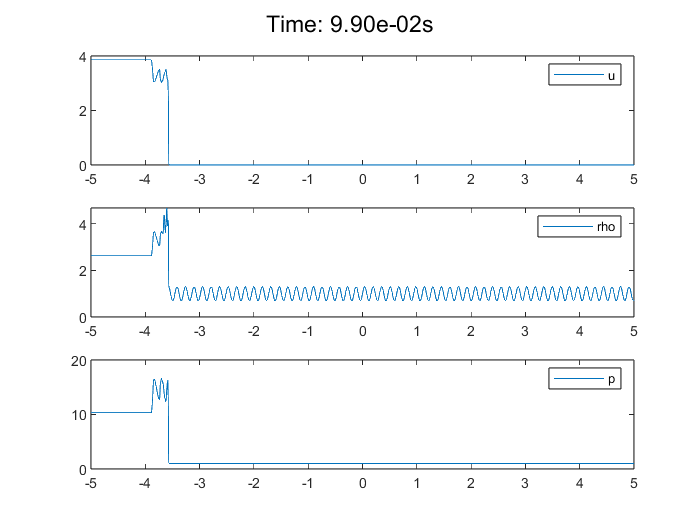

% 设置差分的方法
splitMethod = StegerWarming;
timeForward = RK3;
discreteMethod = WENO;

osher_exact.setSplitMethod(splitMethod);
osher_exact.setTimeForwardMethod(timeForward);
osher_exact.setDiscreteMethod(discreteMethod);

osher_200.setSplitMethod(splitMethod);
osher_200.setTimeForwardMethod(timeForward);
osher_200.setDiscreteMethod(discreteMethod);

% 采用差分方法推进到0.1s
idx = 0;
for i = 0:dt:0.1
    idx = idx + 1;
    osher_exact.timeStep(); % 推进2000个网格点的算例
    osher_200.timeStep(); % 推进200个网格点的算例
    if mod(idx,10) == 0 || idx == 1
        sgtitle(sprintf('Time: %.2ds',i));
        osher_exact.show();
        pause(0.1);
    end
end

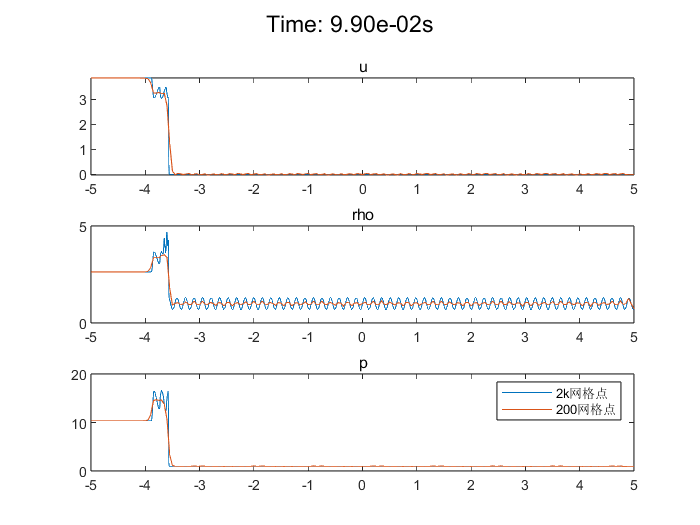

% 2000个网格点和200个网格点的对比
subplot(311)
plot(osher_exact.x,osher_exact.u,osher_200.x,osher_200.u)
title('u')

subplot(312)
plot(osher_exact.x,osher_exact.rho,osher_200.x,osher_200.rho)

title('rho')

subplot(313)
plot(osher_exact.x,osher_exact.p,osher_200.x,osher_200.p)

title('p')

legend('2k网格点','200网格点');